# Práctica 1 - Tipo B

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### a) Modelar el sistema propuesto

Nos encontramos ante un modelo presa-depredador siendo los agentes que interviene leucocitos y bacterias (en adelante L y B), las variables que intervendrán son:

$d_i =$ factor de defensa del agente $i$

$a_i =$ factor de ataque del agente $i$

$L_n =$ población de leucocitos en el instante n

$B_n =$ población de bacterias en el instante n

$t_n =\;$variable genérica de tiempo en el instante n

Ecuación del modelo (enunciado): 


$$\Delta L=d_L \cdot L_n -a_B \cdot B_n$$



$$\Delta B=d_B \cdot B_n -a_L \cdot L_n$$


Es decir:


$$L_{n+1} =L_{n\;} +d_L \cdot L_n -a_B \cdot B_n$$



$$B_{n+1} =B_{n\;} +d_B \cdot B_n -a_L \cdot L_n$$


Simplificando:


$$L_{n+1} =\left(1+d_L \right)\cdot L_n -a_B \cdot B_n$$



$$B_{n+1} =\left(1+d_B \right)\cdot B_n -a_L \cdot L_n$$


Condiciones iniciales: $L_0 =8000;\;B_0 =10000$

Inicio: $t_{inicial} =0$    Fin: $t_{fin} =50$ (por ejemplo)

Nota: Las unidades de tiempo no se especifican, lo tratamos de manera genérica.

Para modelar con simulink definiremos las variables mencionadas anteriormente, gracias a que simulink tiene acceso a las variables del workspace.

% Condiciones iniciales
L0 = 8000; % L(0) = 8000 leucocitos
B0 = 10000; % B(0) = 10000 bacterias

% Constantes globales
% Factores de ataque y defensa
dL = -0.5; aL = 0.05; % Ejemplo inicial arbitrario
dB = 0.1; aB = -0.4; % Ejemplo inicial arbitrario

A continuación configuramos los parámetros de simulación y de dibujo

model_name = "modelo_LB";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 50; % Tiempo arbitrario
solver.step = 1;

Configuración dibujos gráfica

% plot settings
pl = struct();
pl.linespec = ".-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "n"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "Poblaci\'on(n)";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Leucocitos vs Bacterias";
labels.title.interpreter = "none";

Y convertimos las ecuaciones y las variables a un modelo en simulink

- Véase modelo_LB.slx

A continuación, desde el livescript ejecutaremos el .slx para ello utilizamos la configuración anterior, para ello al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;

    plot(signal.Time, signal.Data, pl.linespec, ...
        MarkerSize=pl.mkr.sz, ...
        DisplayName=signal.Name);
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

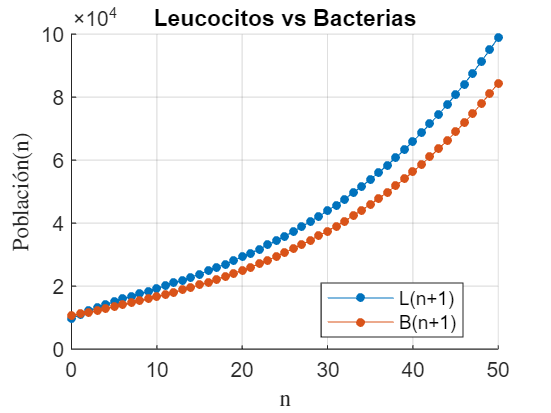

set_labels(labels)
hold off

### b) Estudiar analíticamente su estabilidad

Para ello realizaremos la matriz jacobiana del sistema y analizaremos sus autovalores.


$$L_{n+1} =\left(1+d_L \right)\cdot L_n -a_B \cdot B_n =f_{\;1}$$



$$B_{n+1} =\left(1+d_B \right)\cdot B_n -a_L \cdot L_n =f_{\;2}$$


Se deben calcular los autovalores de la matriz jacobiana de la siguiente función vectorial:


$$f\left(L_n \;,\;B_n \right)=\left(f_{\;1} \left(L_n \;,B_n \right)\;,\;f_{\;2} \left(L_n \;,B_n \right)\right)$$


syms Ln Bn dL dB aL aB
% Definimos la función vectorial
f = [(1+dL)*Ln - aB*Bn, ...
     -aL* Ln + (1+dB)*Bn];
% Calculamos su matriz jacobiana
J = jacobian(f, [Ln, Bn])

$$J = \left(\begin{array}{cc} \mathrm{dL}+1 & -\mathrm{aB}\\ -\mathrm{aL} & \mathrm{dB}+1 \end{array}\right)$$

% Calculamos sus autovalores
autovalores = eig(J)

$$autovalores = \left(\begin{array}{c} \frac{\mathrm{dB}}{2}+\frac{\mathrm{dL}}{2}-\frac{\sqrt{{\mathrm{dB}}^{2}-2\,\mathrm{dB}\,\mathrm{dL}+{\mathrm{dL}}^{2}+4\,\mathrm{aB}\,\mathrm{aL}}}{2}+1\\ \frac{\mathrm{dB}}{2}+\frac{\mathrm{dL}}{2}+\frac{\sqrt{{\mathrm{dB}}^{2}-2\,\mathrm{dB}\,\mathrm{dL}+{\mathrm{dL}}^{2}+4\,\mathrm{aB}\,\mathrm{aL}}}{2}+1 \end{array}\right)$$

La estabilidad dependerá del módulo de los autovalores, será estable si su módulo es menor o igual que 1, teniendo en cuenta que en caso de ser 1 ese autovalor debe tener multiplicidad simple.

vars = [dL, dB, aL, aB];
% Se deben resolver
eq1 = abs(autovalores(1)) <= 1;
eq2 = abs(autovalores(2)) <= 1;
% sol = solve([eq1, eq2], vars)

No es posible para MATLAB encontrar y elegir un conjunto de soluciones, tomaremos valores arbitrarios para los 3 posibles casos.

Que son:

 $\left|\lambda_1 \right|<1$ y $\left|\lambda_2 \right|<1$ entonces estable

$\left|\lambda_1 \right|>1$ y $\left|\lambda_2 \right|>1$ entonces inestable

$\left|\lambda_1 \right|>1$ y $\left|\lambda_2 \right|<1$ o $\left|\lambda_1 \right|<1$ y $\left|\lambda_2 \right|>1$

entonces punto de ensilladura

### c) Determinar cuál es la capacidad ofensiva y defensiva de ambos organismos para que no haya ni vencedores ni vencidos.

Esto es un caso de estabilidad en el que suponemos que las poblaciones de ambos organismos sobreviven, es decir $L_n \not= 0$ y $B_n \not= 0$ para $n\to \infty$

Las capacidades de los organismos se obtienen de resolver las inecuaciones:

eq1 = abs(autovalores(1)) <= 1

$$eq1 = \left|\frac{\mathrm{dB}}{2}+\frac{\mathrm{dL}}{2}-\frac{\sqrt{{\mathrm{dB}}^{2}-2\,\mathrm{dB}\,\mathrm{dL}+{\mathrm{dL}}^{2}+4\,\mathrm{aB}\,\mathrm{aL}}}{2}+1\right|\leq 1$$

eq2 = abs(autovalores(2)) <= 1

$$eq2 = \left|\frac{\mathrm{dB}}{2}+\frac{\mathrm{dL}}{2}+\frac{\sqrt{{\mathrm{dB}}^{2}-2\,\mathrm{dB}\,\mathrm{dL}+{\mathrm{dL}}^{2}+4\,\mathrm{aB}\,\mathrm{aL}}}{2}+1\right|\leq 1$$

Valores arbitrarios que cumplen las ecuaciones anteriores para


$$L_{n+1} =\left(1+d_L \right)\cdot L_n -a_B \cdot B_n$$



$$B_{n+1} =\left(1+d_B \right)\cdot B_n -a_L \cdot L_n$$


### d) Si los enfrentamientos terminaran cuando alguno de los dos organismos desapareciera, ¿cuánto duraría dicho enfrentamiento? ¿Quién resultaría vencedor?

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

#### *Decorador de la función sim de MATLAB

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

#### *Configuración xlabel, ylabel, title de MATLAB

Esta función configura las etiquetas de la figura actual. Recibe una variable struct con la configuración de las etiquetas.

function set_labels(labels)
title(labels.title.name, Interpreter=labels.title.interpreter)
xlabel(labels.x.name, Interpreter=labels.x.interpreter);
ylabel(labels.y.name, Interpreter=labels.y.interpreter);
end

#### Consideraciones adicionales Simulink

Se utiliza el bloque Out1 para cada señal debido a que:

- No usaremos bloques Bus para no formatear los nombres, ejemplo: MATLAB transforma '+' a '_'

- No usaremos bloques To Workspace para iterar más fácil, iteramos el contenido de .yout

- Es posible el manejo de múltiples condiciones iniciales sin problema

Autor: Alfredo Robledano Abasolo 3ºB Ingeniería Matemática UFV (2023-2024)